# Spectrogram


[audioIn,fs] = audioread("measurment-2/jumps/230428-006-jump1-5m.wav")

audioIn =    -0.0029         0
   -0.0047         0
   -0.0037         0
   -0.0035         0
   -0.0054         0
   -0.0052    0.0000
   -0.0050   -0.0001
   -0.0044    0.0001
   -0.0064   -0.0001
   -0.0044    0.0001


fs = 48000


S = melSpectrogram(audioIn,fs);

[numBands,numFrames] = size(S);
fprintf("Number of bandpass filters in filterbank: %d\n",numBands)

Number of bandpass filters in filterbank: 32



fprintf("Number of frames in spectrogram: %d\n",numFrames)

Number of frames in spectrogram: 4000


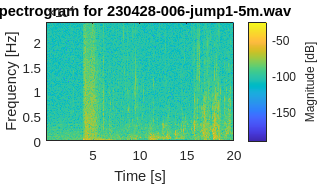


fig = figure('Position', [10 10 350 200]);
% Compute the spectrogram
windowLength = 2048;
hopLength = 512;
[~, f, t, p] = spectrogram(audioIn(:,1), hamming(windowLength), windowLength - hopLength, windowLength, fs, 'yaxis');

% Plot the spectrogram
imagesc(t, f, 10*log10(abs(p)));
axis xy;
xlabel('Time [s]');
ylabel('Frequency [Hz]');
title('Spectrogram for 230428-006-jump1-5m.wav');

% Add colorbar with label
c = colorbar;
c.Label.String = 'Magnitude [dB]';
%t     = (0:1/fs:(length(ExcitationSignal)-1)/fs)';
%p = plot(t, ExcitationSignal);
%p.Color = [0 0 1];
%p.LineWidth = 2;
%grid on;
%xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
%ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
%title('Excitation Signal, Impulse at $t=3\; \mathrm{s}$', 'FontSize', SETTINGS.subtitleFS);
%xticks(0:1:duration_s);
%ylim([-1 1]);
exportgraphics(fig, 'spectre.pdf', 'Resolution', 200);